# Working with Numeric Data

[⇦ Overview](matlab: open("Overview.html"))

All digital computers are fundamentally operating on and with numbers. Nearly all commercial computers are binary, meaning they operate on binary digits (bits) that can take two values: 0 or 1. Quantum computers are outside the scope of this example. 

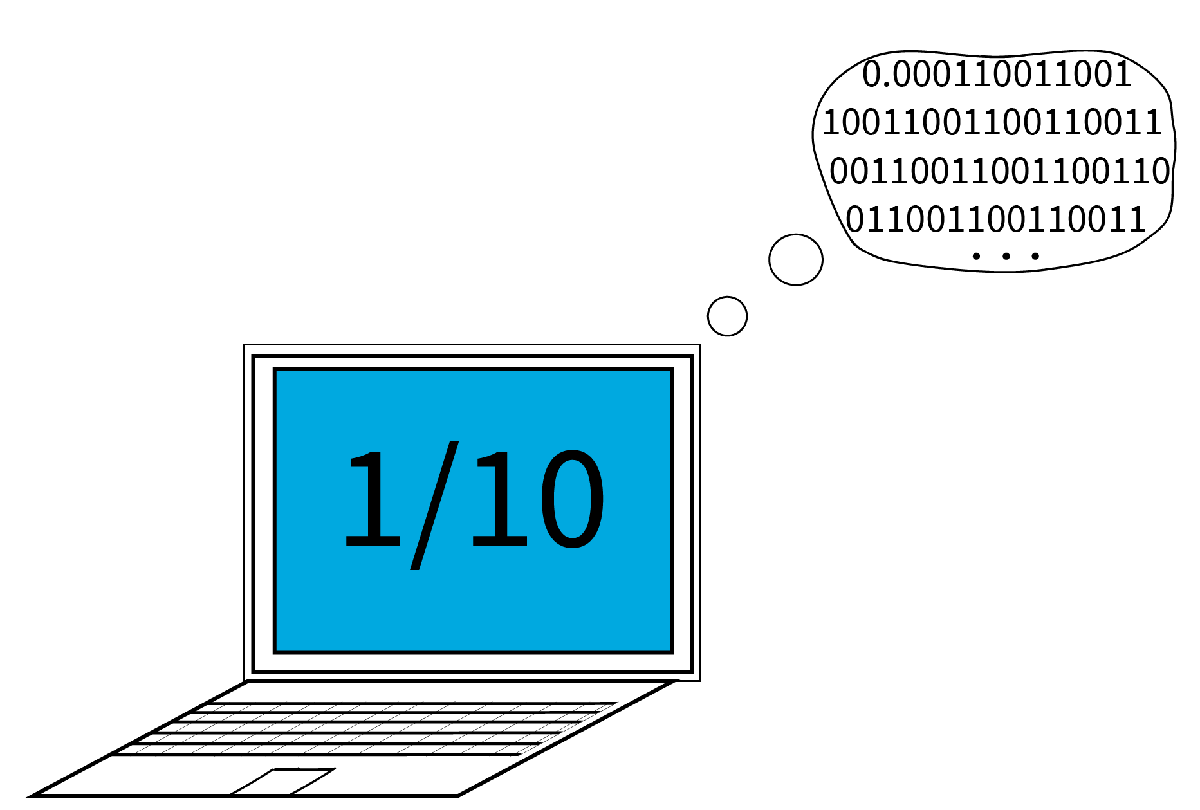

Remembering the binary nature of a computer can help you choose the most efficient numeric data type for your problem.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one.

## Representing Numbers

You probably think of `4` and `-2` and `3.2` as numbers, but a computer makes distinctions between numbers based on their internal representation, which is called a *data type*. Here are a few common data types for numbers:

- floating point (`single`, `double`)

- boolean (`logical`, `true`, `false`)

- unsigned integer (`uint8`, `uint16`, `unint32`, `uint64`)

- signed integer (`int8`, `int16`, `int32`, `int64`)

## Integers

Most computers store data in the form of binary codes. Each of these data types has its own translation rule and size limitations. For instance, an 8-bit unsigned integer is simply the binary expression of the corresponding integer:

$7 = 0*2^7+0*2^6+0*2^5+0*2^4+0*2^3+1*2^2+1*2^1+1*2^0$ `= 00000111 (base 2)`

Continuing the count, we can represent numbers from `0` up to 

$255 = 1*2^7+1*2^6+1*2^5+1*2^4+1*2^3+1*2^2+1*2^1+1*2^0$ `= 11111111 (base 2).`

There is a clear path to larger values by using more bits. 

 **Reflect.**

- What is the largest unsigned integer that could be represented with 9 bits? What about 4 bits?

This doesn't make any allowance for negative values, however. To represent $-2$ as an 8-bit signed integer, we have to be a little more clever. First, use one bit to note if the value is positive (0) or negative (1). Then, there are 7 bits left, giving us values from -127 to 127. Careful encoding allows the actual range of values for an 8-bit signed integer to be -128 to 127. 

You can search for information in the documentation using the command `doc` followed by either a function name or a search term. Run this section to open up a documentation window. Select the first result to learn more about integer data types.

doc integers

  **Pro-tip**. Run this section by selecting   **Run Section** in the **Live Editor **tab or typing Ctrl+E (on macOS systems, use Command+E)**. **

## **Floating Point**

Because of the general applicability of floating point numbers, the default numerical type in MATLAB is a double-precision (binary64) floating point, or `double`. [Floating point data types](https://www.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html) are defined by the IEEE® Standard 754. The basic information required for working with floating point numbers was covered in [Fundamentals of Programming](https://www.mathworks.com/matlabcentral/fileexchange/103225-fundamentals-of-programming), but let's delve a little deeper. Scientific notation is structured with a sign, significant figures, and an exponent, all expressed in base 10. 

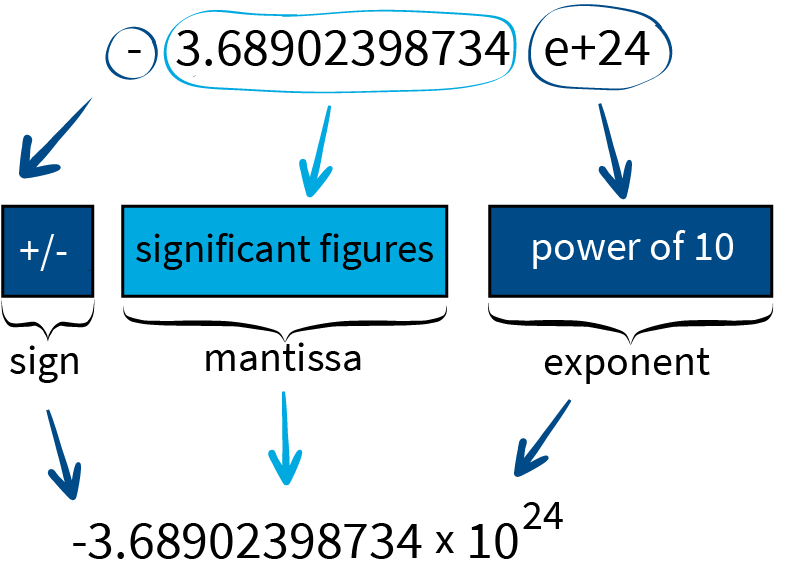

Floating point representation is similar to scientific notation but is stored and operated on in a binary system. A single-precision floating point number consists of 32 binary digits (bits). The first (or *high)* bit encodes the sign with `0` being positive and `1` being negative. The next 8 bits encode the exponent with a *bias *of 127. Remembering the range of values for `uint8` is $[0,255]$ this bias means that the exponent can take values from $[0,255]-[127,127] = [-127,128]$. The final 23 bits encode the fraction, $f$, in the decimal $1.f$. This "significand" does not need to store the unit part because, in a binary scientific number, this digit is always one until we reach the minimum possible value of the exponent. 

### Special Floating Point Numbers

Floating point arithmetic is designed to be mathematically complete. This requires the existence of several special symbols to label these ideas.

#### Signed Zero

Because of the sign bit, the value of `0` can be either `+0` or `-0`. This can be important in calculations because a floating point "`0`" represents a set of values in the interval determined by the smallest possible increment around `0,` `[`-`eps(0),eps(0)]`, so that sign can make a difference in calculations. Mathematically, this tracks whether `0` was being approached from the left or the right along a horizontal number line.  

a = -1.007/1.96e308  % Calculate a value that will underflow to -0
5/a                  % Check that this value retains information about how it is approaching 0

While MATLAB implements IEEE standard floating point arithmetic, it will always display `0` as an unsigned value. This can simplify the use of logical checks since

a == 0     % This is a true statement
-0 == 0   % Writing this out explicitly

even though

1/a == 1/0  % Check the logical equivalence of the inverses

#### Signed Infinity

There are two values labeled `+Inf` and `-Inf,` which result if you exceed the boundaries of your floating point system with values that are too large in absolute value to be represented. For example, 

1/0
1/a

When applying your mathematical intuition, remember that a floating point `0` should be treated as a limit approaching zero.  Because of the rounding, each floating point zero might be precisely zero but is more likely to be a very tiny positive or negative value below the resolution of the data type. 

#### NaN

The final example represents a value that is not a number, `NaN`. This value results from attempting mathematically undefined operations where even their limiting values cannot be uniquely determined.

Inf * 0
Inf - Inf

A value of `NaN` may also be used to represent non-existent values, such as in a collection of data where some measurements were not recorded. 

** Exercise 1.**

Use what you know about floating point numbers to create an example where the symbolic computation and floating point computation result in different values.

** Exercise 2.**

By referencing the documentation on integers, select the range of values that can be represented by a 32-bit unsigned integer:

a) $0$ to $2^8-1$, that is 0 to 255

b) $0$ to $2^{16}-1$, that is 0 to 65,535

c) $0$ to $2^{32}-1$, that is 0 to 4,294,967,295

d) $0$ to $2^{64}-1$, that is 0 to 18,446,744,073,709,551,615

e) $-2^7$ to $2^7-1$, that is -128 to 127

f) $-2^{15}$ to $2^{15}-1$, that is -32768 to 32777

g) $-2^{31}$ to $2^{31}-1$, that is - 2147483648 to 2147483647

h) $-2^{63}$ to $2^{63}-1$, that is - 9,223,372,036,854,775,808 to 9,223,372,036,854,775,807

answer = "No answer";  % Selecting an option will cause this code to run
checkExercise2(answer)

  **Pro-tip**. You can learn more about how MATLAB implements numbers, including the encoding used for signed integers, by reading about [Bit-Wise Operations](https://www.mathworks.com/help/matlab/matlab_prog/bit-wise-operations.html).

## Interactions of Numeric Data Types

Consider the differences when you run the following:

3+5                    % Operating on doubles
3+int8(5)              % Operating with doubles and signed 8-bit integers
35/65                  % Operating on doubles
uint8(35)/65           % Operating with unsigned 8-bit integers and doubles
-2*3.2                 % Operating on doubles
int16(-2)*3.2          % Operating on signed 16-bit integers and doubles
uint8(-2)*3.2          % Operating on unsigned 8-bit integers and doubles

Note that the answer output is labeled with the data type it inherits. If you do not specify a data type, MATLAB uses the 64-bit floating point numeric data type `double` for any unspecified numeric data type. That is why you see 

in the original example. You might also notice that this answer has extra trailing 0's while the result for `35/65` is not exact. 


$$0.5385 = \frac{1077}{2000} \neq \frac{7}{13} = \frac{35}{65}$$


This is an example of the choice of precision-how many decimal places are displayed in the result. By default, MATLAB presents four digits after the decimal point. For larger (or smaller) numbers, the results will be printed in scientific notation to 5 significant digits. As you know, however, the programmatic representation of the number is still a 64-bit double, so if you want to see more precise expressions, you can by resetting the desired format:

format long
35/65
format short
35/65

For additional options, you can read the help page:

help format

  **Pro-tip**. The command `format` is an example of an *environmental variable*. This is a setting whereby the programmer can control how a programming system behaves in a way that applies to all interactions until the programmer changes it again. 

** Exercise 3.**

Using the documentation search to identify the proper commands, write code to evaluate the inverse sine of $\frac{\sqrt{3}}{2}$. Express your answer in degrees as a signed 8-bit integer.

  **Pro-tip**. If you know the command for a related function, like `sin`, scrolling down to the "See Also" list at the bottom of the documentation page will frequently direct you towards the function you might be looking for. 

% Use this code block to search for documentation and calculate the
% inverse sine of sqrt(3)/2.

doc sin
doc square root MATLAB


 **Reflect.**

- What other functions or operations might you want to use? Can you find them? Do they work the way you expect?

## Further Exploration

Another standard numeric data type is hexadecimal, which is base 16. You may have encountered [hexadecimal representations](http://mathworks.com/help/matlab/creating_plots/specify-plot-colors.html) of colors. In general, hexadecimal is a more human-readable representation than binary if you need to work at a byte level. 

a = 0xFF
b = 0x2A
c = 0b101010

Learn more in the [documentation](https://www.mathworks.com/help/matlab/matlab_prog/specify-hexadecimal-and-binary-numbers.html). 

[⇦ Return to the navigation page](matlab: open("Overview.html"))

## Helper Functions

function checkExercise2(answer)
if answer == "No answer"
    disp("That is the default. Please select a solution.")
elseif answer == "c"
    disp("That is correct.")
else
    disp("Please try again.")
end
end

%#ok<*EQEFF>
%#ok<*VUNUS>